The kernel super class allows addition subtraction multiplication and division.

A kernel can then be made periodic in a given dimension or set of dimensions with an enforced period.

A kernel matrix can then be constructed using the build method of a kernel.

clear
close all
clc

xx = lhsdesign(2000,3);

a = kernels.EQ(3,[1 1 1]).periodic(1,0.3);

b = kernels.Matern52(2,0.1).periodic(1,0.6);

c = kernels.RQ(2,0.5,0.1);

f = kernels.EPAN(0.5,0.1)

f =   EPAN with properties:

         theta: 0.1000
       kernels: {[1×1 kernels.EPAN]}
    operations: []
       warping: {[1×1 struct]}
        thetas: {[0.1000]}
        scales: {[0.5000]}
         scale: [0.5000]
             w: [1×1 struct]
         signn: [0]
             X: []



zz = kernels.CEQ(1,1,[0.5 0.1 0.4]);

d = a*b + c;

q = kernels.LPEQ(1,[1 1 1]);

q2 = kernels.NN(1,[1 1 1]);

[K] = q2.build(xx,xx);

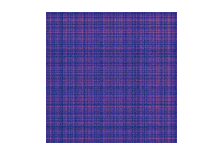


figure
pcolor(real(K))
shading flat
axis off
axis square
utils.cmocean('thermal')

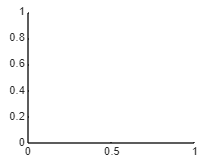

Z = GP([],q2);
x1 = linspace(0,1,30)';

figure
hold on

for i = 1:30
    ysamp = Z.samplePrior(x1);
    plot(x1,ysamp,'LineWidth',0.05,'Color','k')
end

Error using mvnrnd (line 115)
SIGMA must be a positive semi-definite matrix.

Error in GP/samplePrior (line 104)
            y = mvnrnd(0*x(:,1),K);